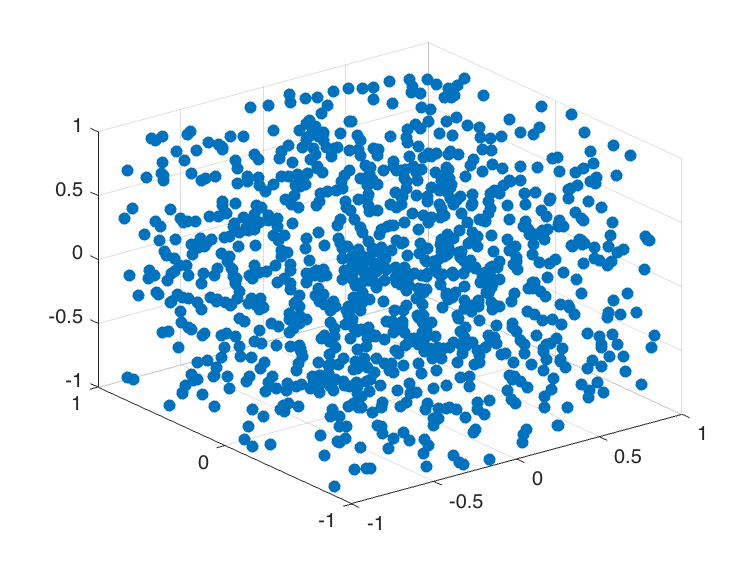

n = 1000;
X = rand(3,n)*2-1;
Y = randn(3,n);
scatter3(X(1,:),X(2,:),X(3,:),'filled');

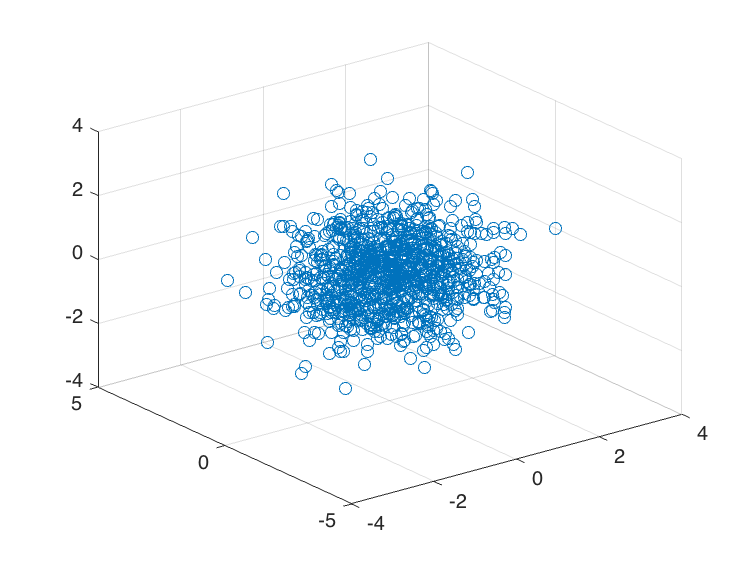

scatter3(Y(1,:),Y(2,:),Y(3,:));

C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = norm(Y(:,i)-X(:,j))^2;
    end
end
r = ones(n,1)/n;
c = ones(n,1)/n;
X0 = r*c';

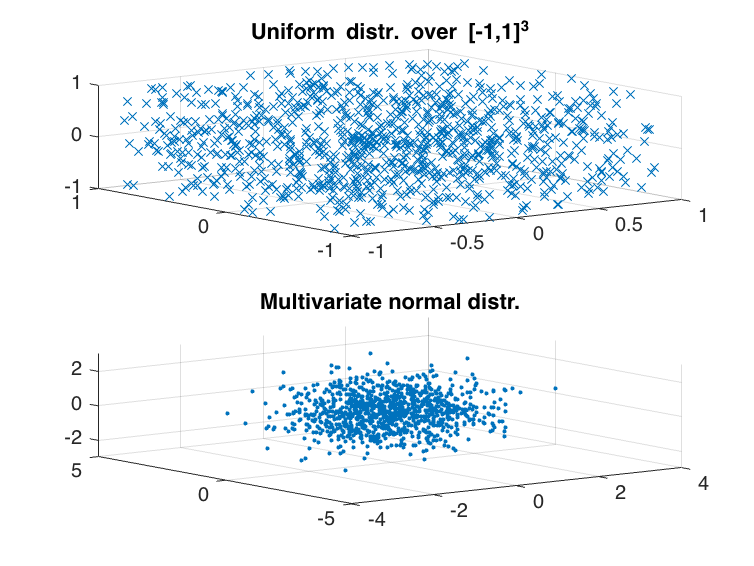

figure
title('3-d case')
subplot(2,1,1);
scatter3(X(1,:),X(2,:),X(3,:),'x');
title('Uniform distr. over [-1,1]^3')
subplot(2,1,2);
scatter3(Y(1,:),Y(2,:),Y(3,:),'.');
title('Multivariate normal distr.')

## Optimal solution

f = reshape(C,[n^2,1]);
x_vec = reshape(X0,[n^2,1]);
A = zeros(2*n,n^2);
for i = 1:n
    A(1:n,(i-1)*n+1:i*n) = eye(n);
    A(n+i,(i-1)*n+1:i*n) = ones(1,n);
end
A = sparse(A);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Vanilla Random Block Coordinate Descent

[fval_rbcd,time_rbcd,feas_rbcd,card_rbcd,X1] = RBCD0(r,c,n,X0,f_opt,C,10000,5000,0);

iter = 1000, accuracy = 0.46168
iter = 2000, accuracy = 0.37182
iter = 3000, accuracy = 0.33473
iter = 4000, accuracy = 0.31852
iter = 5000, accuracy = 0.31648
number of successful iterations =3806


## RBCD-Diagonal Band

[fval_rbcddb,time_rbcddb,feas_rbcddb,X1,card_rbcddb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,1,0); 

iter = 1000, accuracy = 0.44845
iter = 2000, accuracy = 0.33187
iter = 3000, accuracy = 0.27949
iter = 4000, accuracy = 0.24729
iter = 5000, accuracy = 0.22467
number of successful iterations =5000


## RBCD-Submatrix and Diagonal Band

[fval_rbcdsdb,time_rbcdsdb,feas_rbcdsdb,X1,card_rbcdsdb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,0.1,0); 

iter = 1000, accuracy = 0.055601
iter = 2000, accuracy = 0.033428
iter = 3000, accuracy = 0.025499
iter = 4000, accuracy = 0.020871
iter = 5000, accuracy = 0.017651
number of successful iterations =5000


## Accelerated RBCD

[fval_arbcd,time_arbcd,feas_arbcd,X1,card_arbcd] = ARBCD(r,c,n,X0,f_opt,C,100,5000,0);

iter = 1000, accuracy = 0.027036
iter = 2000, accuracy = 0.021236
iter = 3000, accuracy = 0.018197
iter = 4000, accuracy = 0.015931
iter = 5000, accuracy = 0.014226
number of successful iterations =5000


## Plot

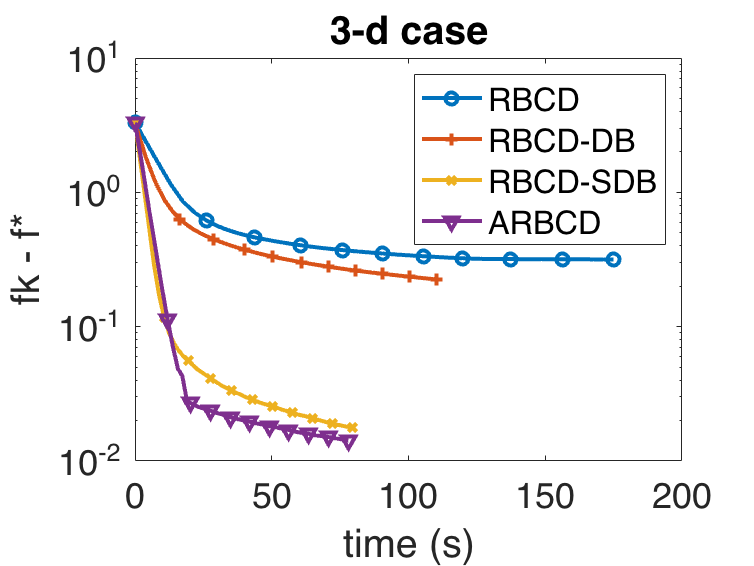

figure
semilogy(time_rbcd,fval_rbcd,'-o','MarkerIndices',1:5:length(fval_rbcd),'LineWidth',2)
hold on
semilogy(time_rbcddb,fval_rbcddb,'-+','MarkerIndices',1:5:length(fval_rbcddb),'LineWidth',2)
hold on
semilogy(time_rbcdsdb,fval_rbcdsdb,'-x','MarkerIndices',1:5:length(fval_rbcdsdb),'LineWidth',2)
hold on
semilogy(time_arbcd,fval_arbcd,'-v','MarkerIndices',1:5:length(fval_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('3-d case')
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',18)

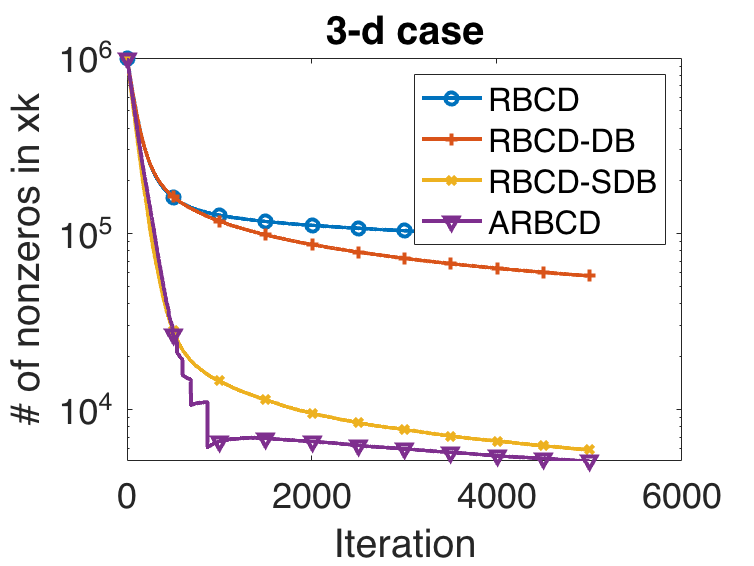

figure
semilogy(card_rbcd,'-o','MarkerIndices',1:500:length(card_rbcd),'LineWidth',2)
hold on
semilogy(card_rbcddb,'-+','MarkerIndices',1:500:length(card_rbcddb),'LineWidth',2)
hold on
semilogy(card_rbcdsdb,'-x','MarkerIndices',1:500:length(card_rbcdsdb),'LineWidth',2)
hold on
semilogy(card_arbcd,'-v','MarkerIndices',1:500:length(card_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('3-d case')
xlabel('Iteration')
ylabel('# of nonzeros in xk')
set(gca,'FontSize',18)